Q-10

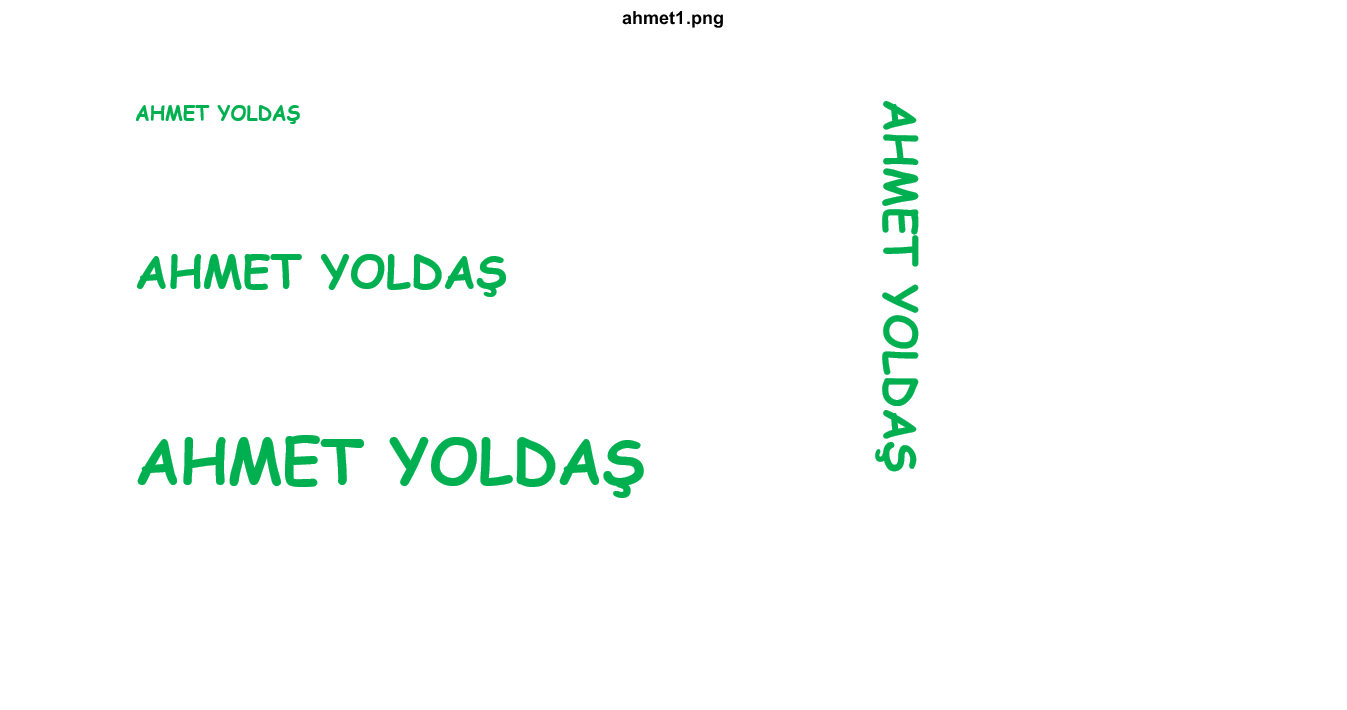

ahmet=imread('C:\Users\ahmet\Desktop\ahmet1.png');
figure;
imshow(ahmet);
title('ahmet1.png');

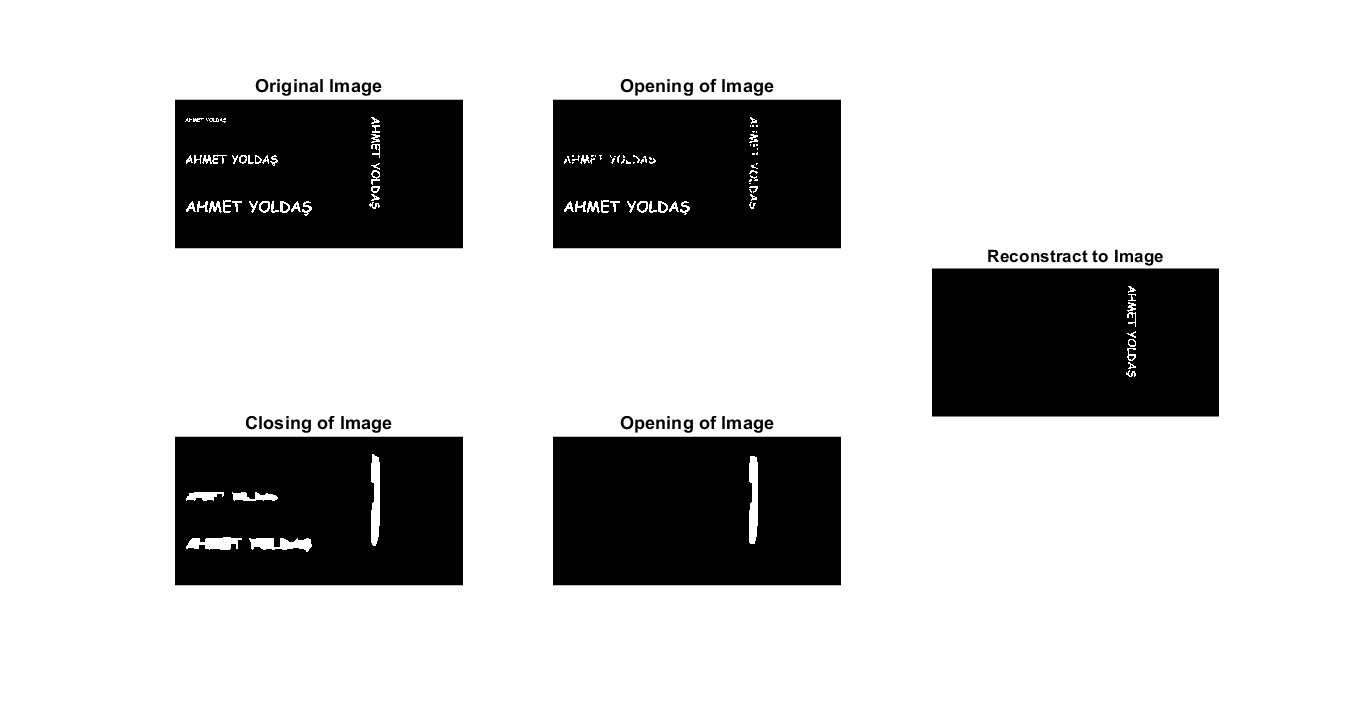

ahmet_b=imbinarize(rgb2gray(im2double(ahmet)));
ahmet_b=imcomplement(ahmet_b);

mask1 = strel('disk',4);
mask2 = strel('rectangle', [60 20]);

im1=imopen(ahmet_b,mask1);
im2=imclose(im1, mask2);
im3=imopen(im2, mask2);
im4=imreconstruct(im3,ahmet_b);

subplot(231)
imshow(ahmet_b);
title("Original Image");

subplot(232)
imshow(im1);
title("Opening of Image");

subplot(234)
imshow(im2);
title("Closing of Image");

subplot(235)
imshow(im3);
title("Opening of Image");

subplot(2,3,[3 6])
imshow(im4);
title("Reconstract to Image");